# LEDS Exam: July 9, 2026

This is the exam project of the course "*Learning and Estimation of Dynamical Systems M" *(**LEDS**), formely called* "Discrete Time System Identification and Control M" *(**SysID**). Remember to follow the text below very carefully to get the best from your project.

Your submission must be a **'.zip' **file with name** 'Surname_Name.zip' **(DO NOT USE ACCENTED CHARACTERS NOR SYMBOLS) with the same internal structure as the one provided in the assignment:

- **Functions**

- **Project_Jul9_2026.mlx **

- **Surname_Name.mlx**

where the folder **Functions **will contain all your implemented functions as well as the provided ones to kick start the project.

**Project_Jul9_2026.mlx **(this file) contains the instructions of the project. 

**Surname_Name.mlx **will be your project file in which you will provide your solution together with a detailed explanation of what you did and why you did it. It will serve as your project report as well.

This means you will also have to add a brief description of the functions you implemented to fullfill the project together with the reasoning behind it. Commenting the functions is good practice, especially if you do so by yourself.

The project file will also have to follow the instructions provided in the project assignment. 

**The project must be done alone. Blind usage of AI is heavily discouraged. Please do the work yourself.**

**The project is due for submission by 23:59 of July 16, 2026. Remember to confirm your final submission on EOL after you upload your solution.**

# Project assignment

clear all
close all
addpath ./Functions;

You will be asked to solve an identification problem in which measurements from the system are available **(1)**, and a classification problem were training features are available and you have to test your result on a test set **(2)**.

## Exercise 1: Estimation 

In this exercise you are asked to estimate an unknown linear model and display it.

To gather system measurements at any point in your code call the function `IdentifyThis.p `with the following inputs:

- Number of samples (`integer`)

N=1000; %set it at a suitable amount 

- Your surname and name with no accents nor special characters (`string`)

Student = 'Luca Hafer';

- Your matriculation number (`string`)

Matriculation = '0001209310';

which finally results in

[Measurements] = IdentifyThis(N, Student, Matriculation);

To collect the measurements it is advised to use this piece of code

u=Measurements.u;
y=Measurements.y;

Then, the identification problem should be solved following the steps below:

- **Understand the model structure**: The provided signals refer to either a FIR or an AR model. You should get the structure straight away from the measurements. Then display a coordinate graph where the x coordinate is the input signal and and the y coordinate is the output signal (something like plot(x,y,'o')), each coordinate couple (u(t),y(t)) should correspond to a point in the plot. The result is different if you do it for an AR or an FIR process.

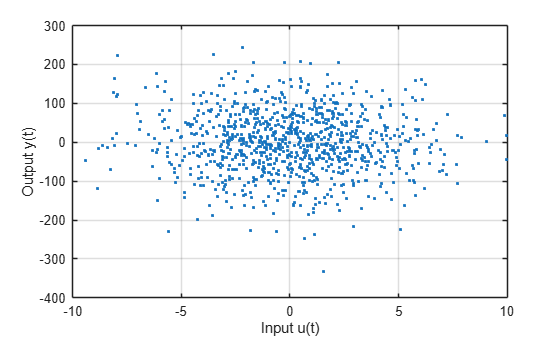

figure;
plot(u, y, '.');
xlabel('Input u(t)');
ylabel('Output y(t)');
grid on;

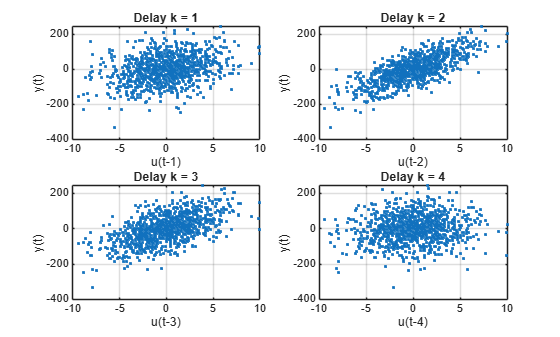


figure;

for k = 1:4
    subplot(2,2,k);
    plot(u(1:end-k), y(k+1:end), '.');
    xlabel(sprintf('u(t-%d)', k));
    ylabel('y(t)');
    title(sprintf('Delay k = %d', k));
    grid on;
end

The scatter plots of $y(t)$ versus the delayed inputs $u(t-k)$ show an approximately linear relationship for some delays. This indicates that the current output can be represented as a linear combination of past input values, which motivates the use of an FIR model:


$$y(t)=b_1 u(t-1)+b_2 u(t-2)+\cdots +b_n u(t-n)+e(t)$$


In particular, the plots suggest a stronger dependence on $u\left(t-2\right)$ and $u\left(t-3\right)$, while the relationship with other delays is weaker. This supports the choice of an FIR model whose regressor contains the relevant delayed input samples.

- **Define the required estimation algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. In this particular case you are asked to implement the recursive version of the estimation algorithm that **uses** the matrix inversion lemma. 

**Description of the algorithm:**

As in RLS I and RLS II, the parameter estimate is updated recursively whenever a new measurement becomes available. The new estimate is obtained by correcting the previous estimate according to the current prediction error:

$\theta (t)=\theta (t-1)+K(t)\varepsilon (t)$,

where


$$\varepsilon (t)=y(t)-\varphi^T (t)\hat{\theta} \left(t-1\right)$$


is the one-step prediction error, and


$$K(t)=\frac{1}{t}R^{-1} \left(t\right)\varphi \left(t\right)$$


is the recursive gain.

The main advantage of RLS III is that the inverse information matrix is not computed from scratch at every iteration. Let


$$S\left(t\right)=\sum_{k=1}^t \varphi \left(k\right){\;\varphi }^T \left(k\right),$$


and define 

$R\left(t\right)=\frac{1}{t}S\left(t\right)$.

It follows that

 $R^{-1} \left(t\right)={\left(\frac{S\left(t\right)}{t}\right)}^{-1} ={t\;\;S}^{-1}$(t).

Therefore,

$K(t)=S^{-1} \left(t\right)\;\varphi \left(t\right)$.

From the recursive update of the information matrix,


$$S\left(t\right)=S\left(t-1\right)+\varphi \left(t\right)\;I\;{\varphi \left(t\right)}^T$$


the inverse would normally have to be recomputed at each new sample. Repeatedly performing a full matrix inversion is computationally expensive, especially for models with many parameters.

By using the matrix inversion lemma

 
$${\left(A+\textrm{BCD}\right)}^{-1} =A^{-1} -A^{-1} B{\;\left(C^{-1} +DA^{-1} B\right)}^{-1} DA^{-1}$$
 

with 


$$A=S\left(t-1\right),\;\;\;\;\;\;\;\;\;B=\varphi \left(t\right),\;\;\;\;\;\;\;\;\;\;C=I,\;\;\;\;\;\;\;\;\;\;D=\varphi T\left(t\right),$$


we can compute the inverse by


$${S\left(t\right)}^{-1} ={S\left(t-1\right)}^{-1} -\frac{{S\left(t-1\right)}^{-1} \varphi \left(t\right)\;\varphi^T \left(t\right){\;S\left(t-1\right)}^{-1} }{I+\varphi^T \left(t\right)\;{S\left(t-1\right)}^{-1} \varphi \left(t\right)}$$


A suitable initialization of the algorithm is $\hat{\theta} \left(0\right)=\theta_0$ and  $S^{-1} \left(0\right)=\alpha I$.

Here, $\alpha$ reflects the uncertainty about the initial guess:

- large $\alpha$: low confidence in  $\theta_0$

- small $\alpha$: high confidence in $\theta_0$

Reasons for a RLS implemantation are:

- its aplication for adaptive systems (in this case not relevant)

- the memory usage (in this case not relevant)

- fault diagnosis

- its application in reals time algorithms (online tracking demonstration underneath)

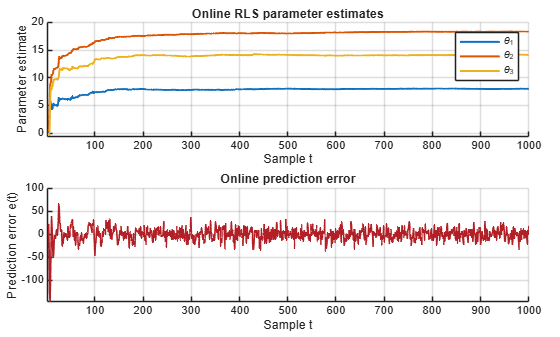


order = 3;
theta0 = zeros(order,1);
alpha = 0.01;

animation = plot_animation(order, N);

theta_hat = estimate_fir_rls3( u, y, order, alpha, theta0, animation);

fprintf('Estimated FIR parameters: %s\n', mat2str(theta_hat'));

Estimated FIR parameters: [8.02881221687494 18.3618896372707 14.1690056708538]


- **Estimate the model order: **describe the criteria you plan to use and add brief description of the matlab function you implemented to do that. Remember to display the final estimated model with the correct order, using the function you implemented for point 2. 

**Description of the criterion:**

The model order was selected using the Minimum Description Length criterion (MDL). The main idea is that the loss function $\[
J\!\left(\hat{\theta}_N\right)
\]$ generally decreases as the model order increases. Therefore, selecting the order by minimizing the loss function alone would tend to favour unnecessarily complex models and may lead to overfitting.

To account for this, the criterion adds a penalty term to the loss function:


$$\[
V\!\left(\hat{\theta}_N\right)
=
N\log\!\left(J\!\left(\hat{\theta}_N\right)\right)
+
f(N,n)
\]$$


where in general

$f(N,p) = Kn\,g(N)$.

For the resulting model-order estimate to be asymptotically consistent, the penalty function must satisfy

$\[
\lim_{N\to\infty} g(N)=\infty
\] $        &     $\[
\lim_{N\to\infty}\frac{g(N)}{N}=0.
\]$    

The first condition ensures that increasingly complex models are penalized as the number of measurements grows, while the second ensures that the penalty grows more slowly than the data-dependent term. These conditions are not satisfied by other criteria like FPE and AIC.

For MDL  $\[
g(N)=\log(N)
\]$ and $K = 1$ resulting in

$\[

{MDL}\,(n)=V\!\left(\hat{\theta}_{N,n}\right)
=
N\log\!\left(J\!\left(\hat{\theta}_{N,n}\right)\right)
+
n\log(N)
\]$.

For an FIR model of order nnn, the MDL criterion is evaluated on the training set for several candidate model orders. The selected order is the one associated with the minimum MDL value:

$\[
\hat{n}_{\mathrm{MDL}}
=
\underset{n}{\arg\min}\;
{MDL}\,(n)
\]$.

The chosen order thus represents a compromise between goodness of fit and model complexity.

(For further implementation details check estimate_fir_order_mdl.mlx)

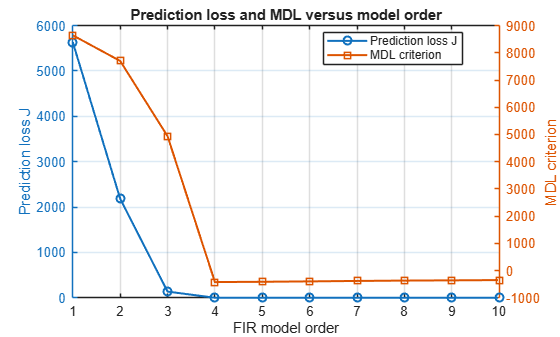

best_order = 4

estimator = @(u, y, n)estimate_fir_rls3(u, y, n, alpha);

best_order = estimate_fir_order_mdl(u, y, 10,estimator, true)

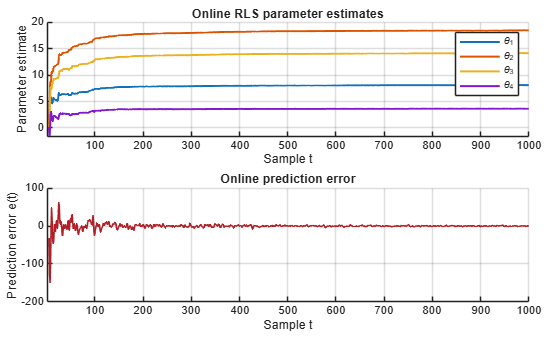

animation = plot_animation(best_order, N);
theta_hat = estimate_fir_rls3( u, y, best_order, alpha, zeros(best_order,1), animation);

- **Validate the model: **describe the criteria with hypothesis testing you plan to use to get model validation and add a description of the matlab functions you implemented to do that. 

After selecting the model order using the Minimum Description Length criterion, the estimated model must be validated to verify whether it provides an adequate representation of the measured system. The validation is based on the prediction residuals


$$\[
\varepsilon(t,\hat{\theta}_N)
=
y(t)-\hat{y}(t,\hat{\theta}_N).
\]$$


If the model has captured the relevant system dynamics, the residual sequence should behave as zero-mean white noise. In particular, its autocorrelation should be zero at every nonzero lag. The following hypotheses are therefore considered:


$$\[
\begin{cases}
H_0:\ \varepsilon(t,\hat{\theta}_N)
      \text{ is zero-mean white noise},\\[4pt]
H_1:\ \text{not }H_0.
\end{cases}
\]$$


(For further description go to gaussian_anderson_whiteness_test.mlx)

Correlations outside bounds: 5/20
Fraction of failed tests: 0.2500
H_0 was rejected: epsilon cannot be assumed to be white noise.


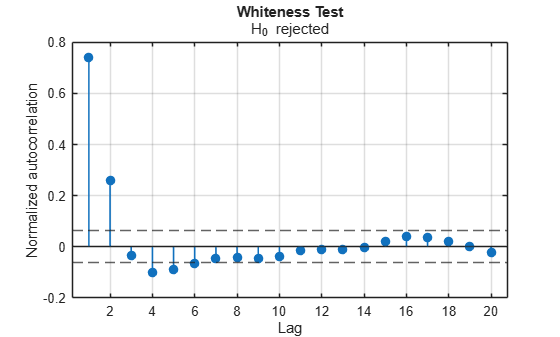

significance_level = 0.05;
residuals = compute_fir_residuals(u, y, theta_hat);
gaussian_anderson_whiteness_test(residuals, 20, significance_level, true);

Although the MDL criterion indicated a 4th-order model, the chi-squared residual whiteness test rejected the null hypothesis under the selected significance level. Therefore, the model order cannot be considered statistically adequate, since its residuals still show significant autocorrelation. This result does not necessarily prove that the model order is too high, but it indicates that the selected structure does not provide an appropriate representation of the measurements. Since the loss function and MDL values observed for the 3rd-order model were already comparatively low, the 3rd-order model will now be evaluated using the same chi-squared whiteness test. This approach was chosen to preserve the originally selected $\alpha$ rather than adjusting it artificially to obtain a the desired test outcome.

animation = plot_animation(3, N);
theta_hat = estimate_fir_rls3( u, y, 3, alpha, zeros(3,1), animation);

Correlations outside bounds: 1/20
Fraction of failed tests: 0.0500
H_0 was accepted: epsilon is zero mean white noise.


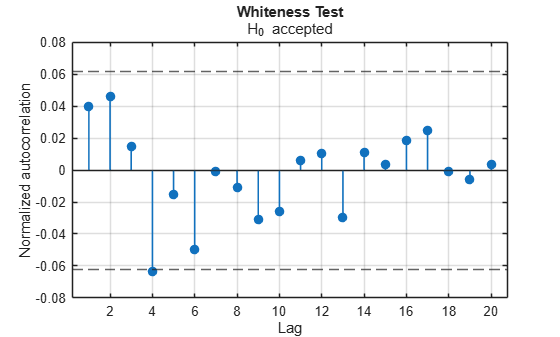

residuals = compute_fir_residuals(u, y, theta_hat);
gaussian_anderson_whiteness_test( residuals, 20, significance_level, true);

The chi-squared residual whiteness test did not reject the null hypothesis for the 3rd-order model.

To further support the choice of model order, a second hypothesis test will be performed to assess the cross-correlation between the input and the residuals. This test verifies whether the residual sequence still contains information related to the input that has not been captured by the model. If the null hypothesis of zero input–residual cross-correlation is also accepted, the 3rd-order model will be chosen. Its computation follows a very similar procedure, differing mainly in the formulated hypotheses 


$$\[
\begin{cases}
H_0: \ \varepsilon(t,\hat{\theta}_N)\ \text{and}\ u(t)\ \text{are uncorrelated},\\[4pt]
H_1: \ \text{not } H_0.
\end{cases}
\]$$


and the normalized test quantities


$$\[
\hat{\gamma}(\tau)
=
\frac{\hat{r}_{\varepsilon u}(\tau)}
{\sqrt{\hat{r}_{\varepsilon}(0)\hat{r}_{u}(0)}},
\qquad
\tau=1,2,\ldots,m.
\]$$


(For further description go to gaussian_anderson_whiteness_test.mlx)

Cross-correlations outside bounds: 1/20
Fraction of failed tests: 0.0500
H_0 was accepted: epsilon and the input are assumed to be uncorrelated.


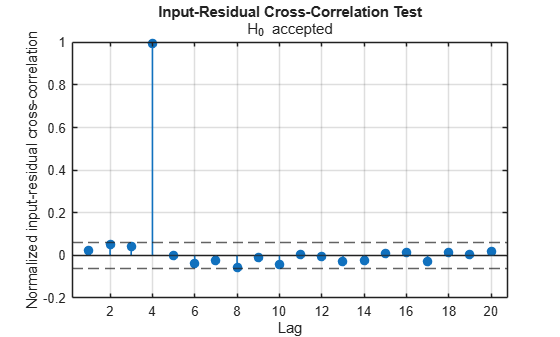

gaussian_anderson_crosscorrelation_test( u(order+1:end), residuals,20, significance_level, true);

As a result, the 3rd order model is selected because it provides an acceptable compromise between model accuracy and generalization. Its residuals satisfy both hypothesis tests. This decision is also consistent with the principle of parsimony, according to which the simplest model that provides an adequate statistical description of the data should be preferred over a more complex alternative.

## Exercise 2: Classification 

In this exercise you are asked to create a classificator from a training set and test it on a new test set..

To gather your set of labelled features at any point in your code call the function `ClassifyThoses.p `with the following inputs:

- Number of samples (`integer`)

N=10; %set it at a suitable amount 

- Your surname and name with no accents nor special characters (`string`)

Student = 'Alice Lenzi';

- Your matriculation number (`string`)

Matriculation = '0001038656';

which finally results in

[FeatureSet] = ClassifyThose(N,Student,Matriculation);

To collect the set it is advised to use this piece of code

Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;

Then, the classification problem should be solved following the steps below:

- **Understand the feature set in space**: The provided training features are scattered in space in a particular (geometrical) way. Understand it and use it to define a "refined" feature set if needed. (Plotting them may result useful). Notice that the training set distribution in space changes at every run of the function, however the boundary shape is always the same. This can be handled easily in a well thought program.

- **Define the required classification algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. Remember to display your estimated classificator.

- **Verify and test your classificator: **verify the obtained classificator on the provided training set and compute the related classification error. Then, try your classificator on the test set and plot your results together with the classification error on the test set.

Remember to add a brief description of the matlab function you implemented accordingly.

**P.S.: **Remember that $\varphi(t)=\left[\begin{array}{l}
1 & \bar u(t)
\end{array}\right]^{T}$ in the case of complex curves.

**P.S.: **Remember that in the case of features representing **more than two classes** you can train a classifier that divides one class with respect to all the others and you can compute one per each class against all the others. In this context, the final prediction is the maximum value obtianed by applying each of the one-vs-the-rest classifiers to a new set of features. **If this is the case, do not plot every single 1vs1 boundary and prediction, just create the final plot with all the boundaries and the relative classes.**

Write an organic **Surname_Name.mlx **file contaning both the explanation and coding that follows the above steps of **BOTH** exercises. This will also be your final project report. Remember to read carefully the exam description with the submission rules.